# Franka Emika Panda Workspace using FK_SpaceForm XZ Plane

clc; clear; close;

#### Start parallel computing pool

pool = parpool();

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 4).


#### Define the transformation matrices for the Franka Emika Panda Robot

panda_model()
M = vpa(M, 4)

$$M = \left(\begin{array}{cccc} 1.0 & 0 & 0 & 0.088\\ 0 & -1.0 & 0 & 0\\ 0 & 0 & -1.0 & 0.926\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

S = vpa(S, 4)

$$S = \left(\begin{array}{ccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 1.0 & 0 & -1.0 & 0 & -1.0 & 0\\ 1.0 & 0 & 1.0 & 0 & 1.0 & 0 & -1.0\\ 0 & -0.333 & 0 & 0.649 & 0 & 1.033 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0.088\\ 0 & 0 & 0 & -0.0825 & 0 & 0 & 0 \end{array}\right)$$

qlim = panda.qlim

qlim =    -2.8973    2.8973
   -1.7628    1.7628
   -2.8973    2.8973
   -3.0718   -0.0698
   -2.8973    2.8973
   -0.0175    3.7525
   -2.8973    2.8973


#### Defining joint limits for $\theta_2, \theta_4, \theta_6$

qlim(1, :) = [0, 0];
qlim(3, :) = [0, 0];
qlim(5, :) = [0, 0];
qlim(7, :) = [0, 0];

vpa(qlim, 5)

$$ans = \left(\begin{array}{cc} 0 & 0\\ -1.7628 & 1.7628\\ 0 & 0\\ -3.0718 & -0.0698\\ 0 & 0\\ -0.0175 & 3.7525\\ 0 & 0 \end{array}\right)$$

#### Generate a set of discrete joint angles within the joint limits

for i=1:size(qlim, 1)
    Qlim(i, :) = linspace(qlim(i, 1), qlim(i, 2), 100);
end
Qlim

Qlim =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -1.7628   -1.7272   -1.6916   -1.6560   -1.6204   -1.5847   -1.5491   -1.5135   -1.4779   -1.4423   -1.4067   -1.3711   -1.3355   -1.2998   -1.2642   -1.2286   -1.1930   -1.1574   -1.1218   -1.0862   -1.0506   -1.0149   -0.9793   -0.9437   -0.9081   -0.8725   -0.8369   -0.8013   -0.7657   -0.7300   -0.6944   -0.6588   -0.6232   -0.5876   -0.5520   -0.5164   -0.4808   -0.4452   -0.4095   -0.3739   -0.3383   -0.3027   -0.2671   -0.2315   -0.1959   -0.1603   -0.1246   -0.0890   -0.0534  

#### Generate all possible combinations of joint angles for the robot

Qxz = unique(combvec(Qlim(2, :), Qlim(4, :), Qlim(6, :))', 'rows')

Qxz =    -1.7628   -3.0718   -0.0175
   -1.7628   -3.0718    0.0206
   -1.7628   -3.0718    0.0587
   -1.7628   -3.0718    0.0967
   -1.7628   -3.0718    0.1348
   -1.7628   -3.0718    0.1729
   -1.7628   -3.0718    0.2110
   -1.7628   -3.0718    0.2491
   -1.7628   -3.0718    0.2871
   -1.7628   -3.0718    0.3252


Q = zeros(size(Qxz, 1), 8);
Q(:, 2) = Qxz(:, 1);
Q(:, 4) = Qxz(:, 2);
Q(:, 6) = Qxz(:, 3);
Q

Q =          0   -1.7628         0   -3.0718         0   -0.0175         0         0
         0   -1.7628         0   -3.0718         0    0.0206         0         0
         0   -1.7628         0   -3.0718         0    0.0587         0         0
         0   -1.7628         0   -3.0718         0    0.0967         0         0
         0   -1.7628         0   -3.0718         0    0.1348         0         0
         0   -1.7628         0   -3.0718         0    0.1729         0         0
         0   -1.7628         0   -3.0718         0    0.2110         0         0
         0   -1.7628         0   -3.0718         0    0.2491         0         0
         0   -1.7628         0   -3.0718         0    0.2871         0         0
         0   -1.7628         0   -3.0718         0    0.3252         0         0


#### Remove duplicate joint angles

uniqueQ = unique(Q, 'rows');
numDuplicates = size(Q,1) - size(uniqueQ,1)

numDuplicates = 0

####  Compute the forward kinematics for each unique set of joint angles

parfor i = 1:size(uniqueQ,1)
    T1 = FK_SpaceForm(S, M, uniqueQ(i, 1: 7)');
    X(i) = T1(1, 4);
    Y(i) = T1(2, 4);
    Z(i) = T1(3, 4);
end


#### Delete the parallel computing pool

delete(pool);

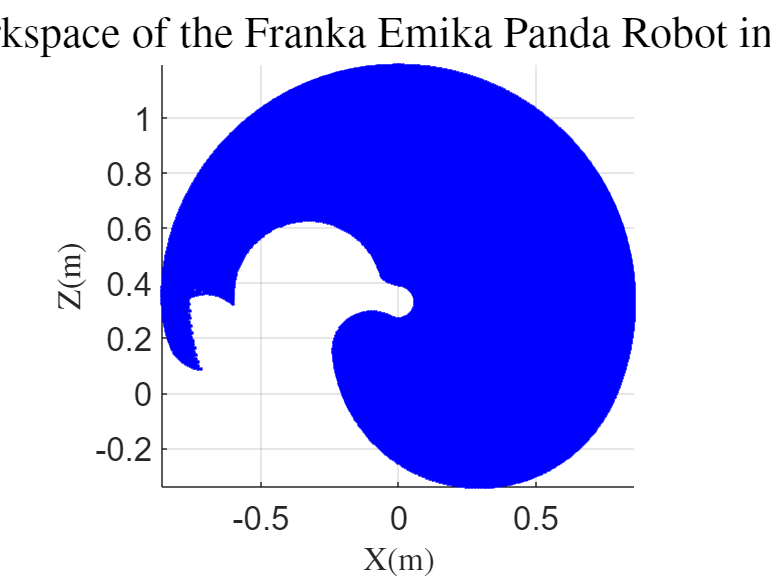

%distance = sqrt(X.^2 + Y.^2 + Z.^2); % compute distance from origin
%c = distance/max(distance); % normalize distances to [0,1]

scatter3(X, Y, Z, 'b.');
% colormap jet; % set the color map
% colorbar; % add a color bar to the plot
ax = gca;
ax.FontSize = 18;
xlabel('X(m)', 'FontSize', 18, 'Interpreter','latex');
ylabel('Y(m)', 'FontSize', 18, 'Interpreter','latex');
zlabel('Z(m)', 'FontSize', 18, 'Interpreter','latex');
title('2-D Workspace of the Franka Emika Panda Robot in XZ Plane', 'FontSize', 24, 'Interpreter','latex');
axis equal;
view(0,0);